clear; close all; clc;
addpath('functions');
addpath('visualization');
addpath('output');

% toggles
sweepHDM = false;
debug    = false;

Nx = 75;    % x spacial grid res
Ny = 75;    % y spacial grid res

% nonlinearity constants
alpha =0.075; % K^-1
T_ref = 300;                        % K

% parameter domain D = [0, 0.5] x [5e-3, 0.025] x [0.4, 0.6]
pts = 10; % discretization

% grid initialization
dx = 1 / (Nx-1);
dy = 1 / (Ny-1);
N  = Nx * Ny;

x_values = linspace(0, 1, Nx);
y_values  = linspace(0, 1, Ny);

% enforcing Dirichlet profile (x = 0)
T_D = @(y, y_bar) (300      .* (y < 1/3) ...
                + (300 + 325 * (sin(3 * pi * abs(y - y_bar)) + 1)) .* (y >= 1/3 & y <= 2/3) ...
                + (300      .* (y > 2/3)));

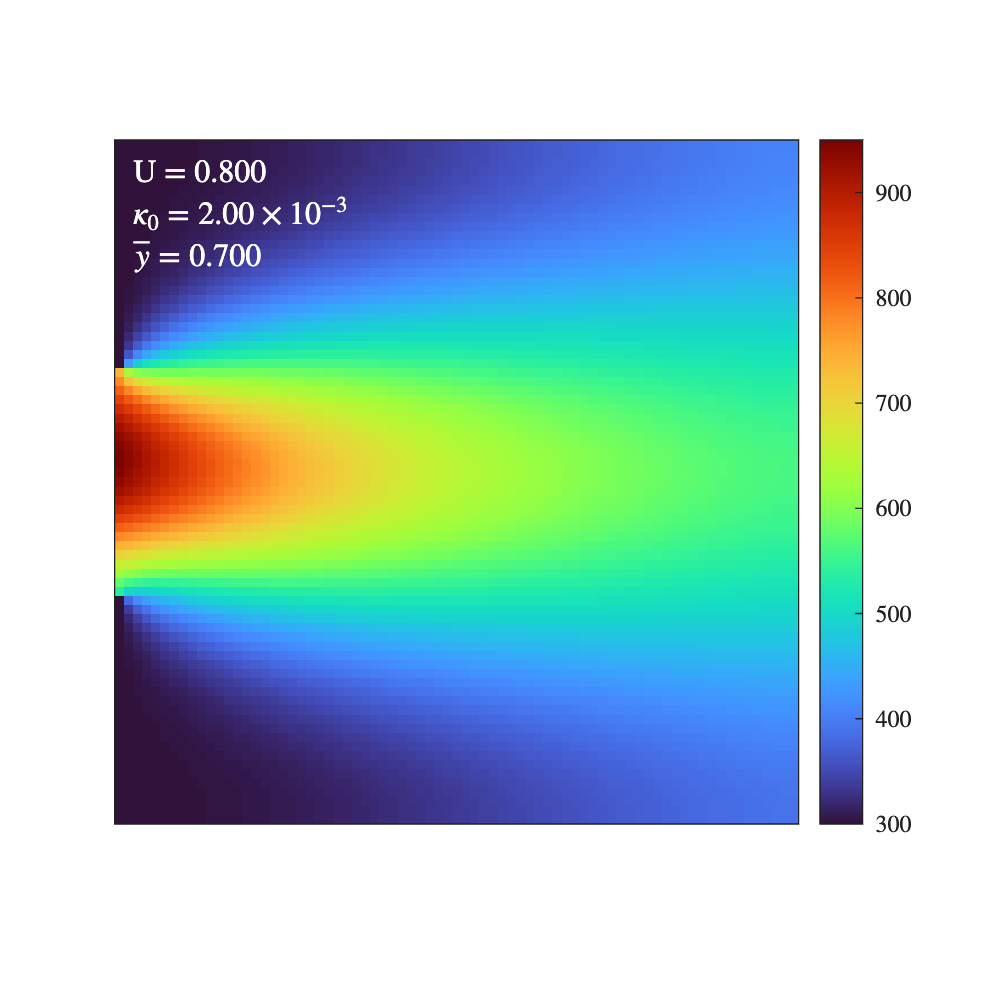

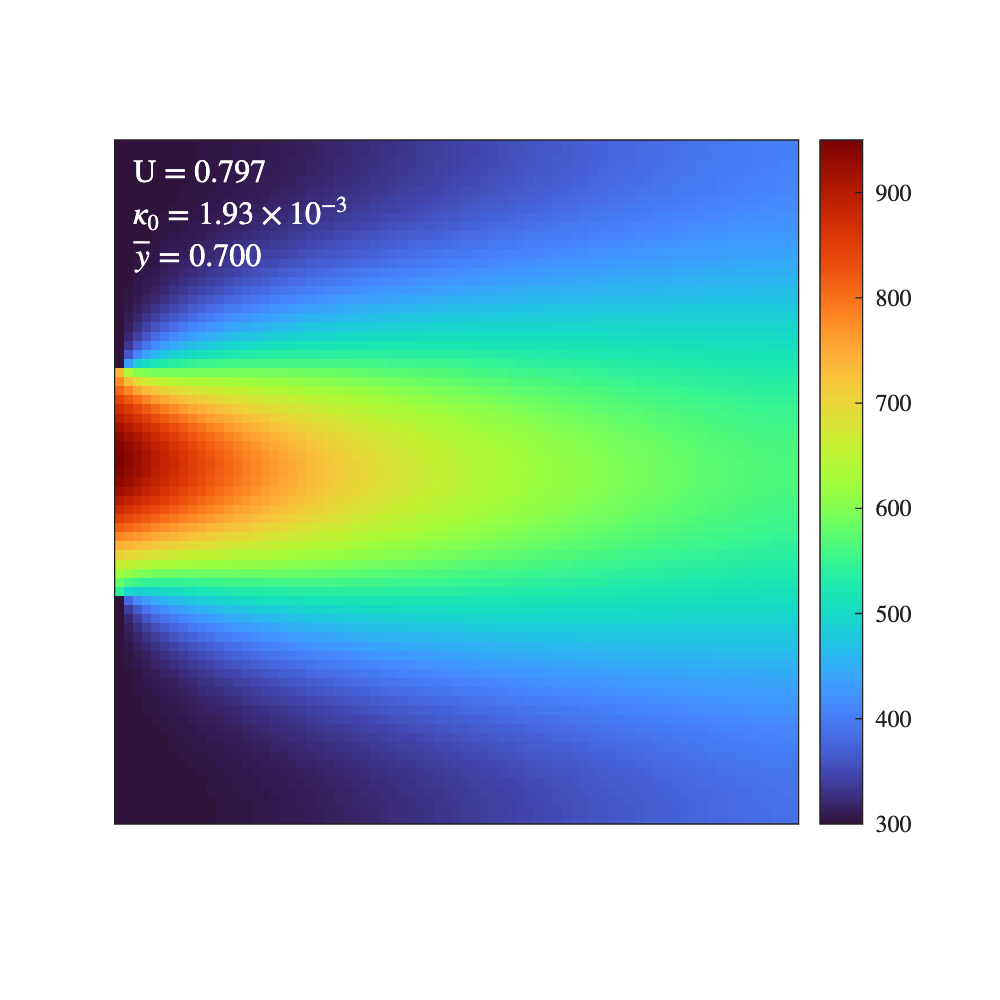

gif_name = 'output/hdm_extreme_loop.gif';

nFrames = 180;     % longer but under 1000
fps     = 60;      % smooth enough
delay   = 1/fps;

% Strong and fast advection
U_mid = 0.50;
U_amp = 0.30;

% VERY low diffusion
kappa_mid = 0.00200;
kappa_amp = 0.00195;

% y_bar varies slowest
ybar_mid = 0.50;
ybar_amp = 0.20;

theta = linspace(0, 8*pi, nFrames+1);  
theta(end) = [];

epsilon  = 1e-6;
max_iter = 200;

% ------------------------------------------------------------
% FIX FIGURE SIZE (CRUCIAL FOR FILE SIZE)
% ------------------------------------------------------------
fig = figure('Color','w','Position',[100 100 500 500]);
ax  = axes(fig);
set(ax,'TickLabelInterpreter','latex');

for i = 1:nFrames
    
    U_val     = U_mid     + U_amp     * cos(1.0*theta(i));
    kappa_val = kappa_mid + kappa_amp * sin(0.25*theta(i));
    ybar_val  = ybar_mid  + ybar_amp  * cos(0.25*theta(i));
    
    mu_k = [U_val, kappa_val, ybar_val];
    
    [w_k, ~, ~] = computeNonLinearHDM( ...
        Nx, Ny, dx, dy, T_D, y_values, ...
        mu_k, alpha, T_ref, epsilon, max_iter);
    
    T_k = reshapeSolution(w_k, Nx, Ny, T_D, y_values, mu_k);
    
    % Inside your loop, after imagesc and colormap
    cla(ax)

    imagesc(linspace(0,1,size(T_k,2)), ...
        linspace(0,1,size(T_k,1)), T_k, ...
        'Parent', ax);

    axis(ax,'xy','equal','tight');
    clim(ax,[300 950]);
    colormap(ax,turbo);

    colorbar(ax,'TickLabelInterpreter','latex');

    % Remove ticks but keep labels
    ax.XTick = [];
    ax.YTick = [];

    x_pos = 0.02;
    y_pos = 0.98;
    line_spacing = 0.06;  % vertical spacing between lines

    % First line: U
    text(x_pos, y_pos, sprintf('U = %.3f', mu_k(1)), ...
        'Units', 'normalized', 'Color', 'w', ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', ...
        'Interpreter', 'latex');

    % Second line: kappa_0 in scientific notation
    mantissa = mu_k(2) / 10^(floor(log10(abs(mu_k(2)))));
    exponent = floor(log10(abs(mu_k(2))));
    kappa_str = sprintf('\\kappa_0 = %.2f \\times 10^{%d}', mantissa, exponent);

    text(x_pos, y_pos - 0.925*line_spacing, ['$' kappa_str '$'], ...
        'Units', 'normalized', 'Color', 'w', ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', ...
        'Interpreter', 'latex');

    % Third line: ybar
    text(x_pos, y_pos - 2*line_spacing, sprintf('$\\bar{y} = %.3f$', mu_k(3)), ...
        'Units', 'normalized', 'Color', 'w', ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', ...
        'Interpreter', 'latex');

    drawnow;
    
    frame = getframe(fig);
    im = frame2im(frame);
    
    % OPTIONAL: shrink resolution further (major size saver)
    im = imresize(im, 0.75);   % reduce to 75% size
    
    % Reduce color palette (huge size reduction)
    [A,map] = rgb2ind(im,128);  
    
    if i == 1
        imwrite(A,map,gif_name,'gif','LoopCount',Inf,'DelayTime',delay);
    else
        imwrite(A,map,gif_name,'gif','WriteMode','append','DelayTime',delay);
    end
end


disp('Optimized HDM loop created successfully.');

Optimized HDM loop created successfully.



function [mantissa, exponent] = log10split(x)
    exponent = floor(log10(abs(x)));
    mantissa = x / 10^exponent;
end